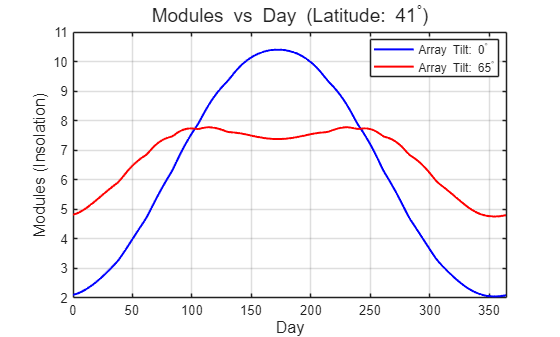

opts = detectImportOptions('D:\SUSTech\大三下\光伏基础\tilt_0.txt');
opts.SelectedVariableNames = {'day', 'modules'};
opts.DataLines = [6, inf]; 

data0 = readtable('D:\SUSTech\大三下\光伏基础\tilt_0.txt', opts);
data65 = readtable('D:\SUSTech\大三下\光伏基础\tilt_65.txt', opts);

days0 = data0.day;
modules0 = data0.modules;

days65 = data65.day;
modules65 = data65.modules;

figure;
plot(days0, modules0, 'b-', 'LineWidth', 1.5); hold on;
plot(days65, modules65, 'r-', 'LineWidth', 1.5);

grid on;
xlabel('Day', 'FontSize', 12);
ylabel('Modules (Insolation)', 'FontSize', 12);
title('Modules vs Day (Latitude: 41^\circ)', 'FontSize', 14);
legend('Array Tilt: 0^\circ', 'Array Tilt: 65^\circ', 'Location', 'best');

xlim([0 365]);